viewer = siteviewer(Basemap="openstreetmap", Buildings="map.osm");

tx = txsite("Name", "Tx_Canyon_Confirmed", ...
    "Latitude", 40.756549, ...
    "Longitude", -73.981883, ...
    "AntennaHeight", 2, ...
    "TransmitterFrequency", 28e9);
show(tx);
rx = rxsite("Name", "Rx_Canyon_Confirmed", ...
    "Latitude", 40.754743, ...
    "Longitude", -73.983610, ...
    "AntennaHeight", 1);
show(rx);

rtpm = propagationModel("raytracing", ...
    Method="sbr", ...
    MaxNumReflections=0, ...
    BuildingsMaterial="perfect-reflector");%, ...
    %TerrainMaterial="perfect-reflector");

los(tx,rx);


rtpm.MaxNumReflections = 10;
clearMap(viewer);
rtpm.BuildingsMaterial = "concrete";
%rtpm.TerrainMaterial = "concrete";
rtpm.MaxNumDiffractions = 0;
raytrace(tx,rx,rtpm)
rays = raytrace(tx,rx,rtpm);

rtPlusWeather = ...
    rtpm + propagationModel("gas") + propagationModel("rain");
raytrace(tx,rx,rtPlusWeather);
rays = raytrace(tx,rx,rtPlusWeather);
ray = raytrace(tx,rx,rtPlusWeather);

rays = rays{1,1};
ss = sigstrength(rx,tx,rtPlusWeather);
disp("Received power : " + ss + " dBm")

Received power : -87.3686 dBm




%increasing directivity
% Design Parameters
HPBW = 30;   % half‑power beamwidth in degrees
SLA  = 50;   % max sidelobe attenuation in dB

azRes = -180:180;  
elRes = -90:90;
[Az,El] = meshgrid(azRes,elRes);

% Simple Gaussian‑horn pattern in dB:
azPat = -min(12*((wrapTo180(Az )/HPBW).^2), SLA);
elPat = -min(12*(((El )/HPBW).^2),      SLA);
magPat = -min( azPat + elPat, SLA );  % combine into one 2‑D pattern

% Create the CustomAntennaElement
hornElem = phased.CustomAntennaElement( 'AzimuthAngles',       azRes,           ...
  'ElevationAngles',     elRes,           ...
  'MagnitudePattern',    magPat           );

% Assign it to your txsite
tx.Antenna      = hornElem;

% Beam steer direction
% NOTE: Use azimuth and elevation angles from tx to rx LOS
azSteer = 90;     % you can compute or adjust this
elSteer = 0;

% % Apply Beam Steering
% steeringVec = phased.SteeringVector('SensorArray', tx.Antenna, ...
%     'IncludeElementResponse', true);
% weights = steeringVec(tx.TransmitterFrequency, [azSteer; elSteer]);
% tx.AntennaAngle = azSteer;  % Point beam main lobe

% Visualize Pattern
clearMap(viewer)
show(rx)
pattern(tx, 'Transparency', 0.6)

show(tx);

aod = ray{1}.AngleOfDeparture;

tx.AntennaAngle = [ 40, -70 ];
pattern(tx,Transparency=0.6);


raytrace(tx,rx,rtPlusWeather);


rays_beam = raytrace(tx,rx,rtPlusWeather);
ss = sigstrength(rx,tx,rtPlusWeather);
disp("Received power: " + ss + " dBm")

Received power: -78.0022 dBm


rays = rays_beam{1,1};

Fs = 20e6;
rtChan = comm.RayTracingChannel(rays,tx,rx);
rtChan.SampleRate = Fs;
rtChan.ReceiverVirtualVelocity = [0; 0; 0];

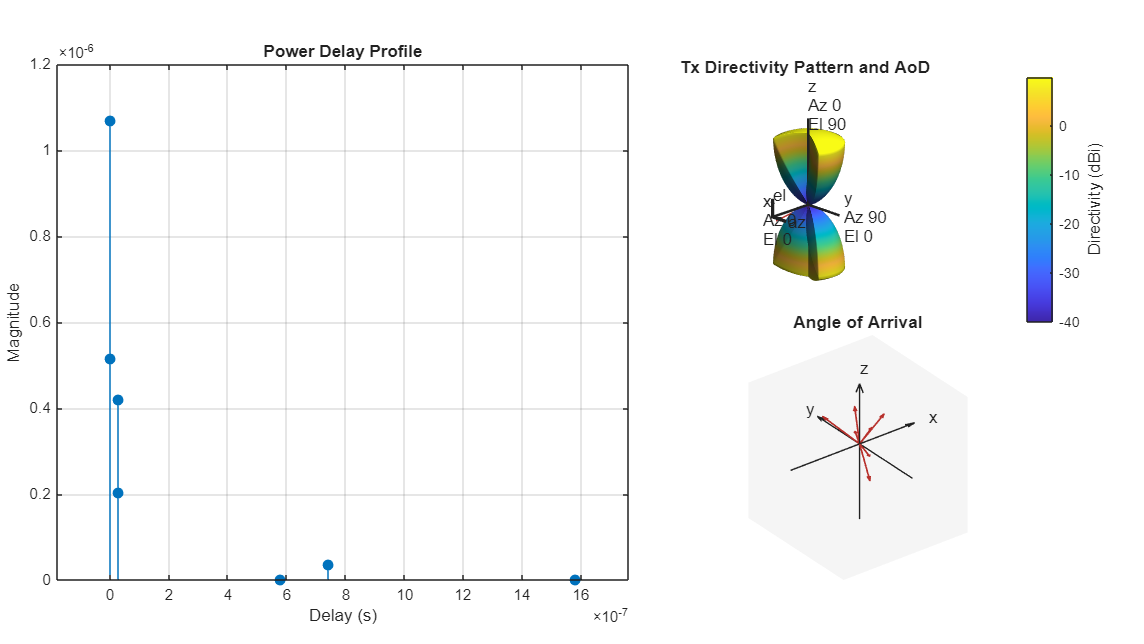

showProfile(rtChan);

rtChanInfo = info(rtChan)

rtChanInfo = struct with fields:
             CarrierFrequency: 2.8000e+10
             CoordinateSystem: 'Geographic'
        TransmitArrayLocation: [3×1 double]
         ReceiveArrayLocation: [3×1 double]
          NumTransmitElements: 1
           NumReceiveElements: 1
           ChannelFilterDelay: 7
    ChannelFilterCoefficients: [7×47 double]
          NumSamplesProcessed: 0
                LastFrameTime: 0


numTx = rtChanInfo.NumTransmitElements;
numRx = rtChanInfo.NumReceiveElements;

modOrder = 16;
bitsPerCarrier = log2(modOrder);
cpLen = 16;                              % Cyclic prefix length
fftLen = 64;                            % FFT length (subcarriers)

% Carrier allocation
numGuardBandCarriers = [6; 5];          % Guard bands on either side
pilotCarrierIdx = [12; 26; 40; 54];  % Pilot indices (typical)
numDataCarriers = fftLen - sum(numGuardBandCarriers) - length(pilotCarrierIdx);

% OFDM Symbol Configuration
numOFDMSymbols = 100;                   % For simulation duration
totalBits = numDataCarriers * numOFDMSymbols * bitsPerCarrier;



% OFDM Modulator Setup (Transmit)
ofdmMod = comm.OFDMModulator(...
    'FFTLength', fftLen, ...
    'NumGuardBandCarriers', numGuardBandCarriers, ...
    'InsertDCNull', true, ...
    'PilotInputPort', true, ...
    'PilotCarrierIndices', pilotCarrierIdx, ...
    'CyclicPrefixLength', cpLen, ...
    'NumSymbols', numOFDMSymbols, ...
    'NumTransmitAntennas', numTx);

% OFDM Demodulator (Receive)
ofdmDemod = comm.OFDMDemodulator(ofdmMod);
ofdmDemod.NumReceiveAntennas = numRx;

constDiagram = comm.ConstellationDiagram(...
    'ReferenceConstellation', qammod(0:modOrder-1, modOrder, 'UnitAveragePower', true), ...
    'XLimits', [-2 2], 'YLimits', [-2 2]);

% Eb/No → SNR conversion
EbNo = 5;                          % in dB
SNR = convertSNR(EbNo, "ebno", ...
    "BitsPerSymbol", bitsPerCarrier, ...
    "CodingRate", 1);              % No coding, so rate = 1
SNRLin = 10^(SNR/10);              % Linear

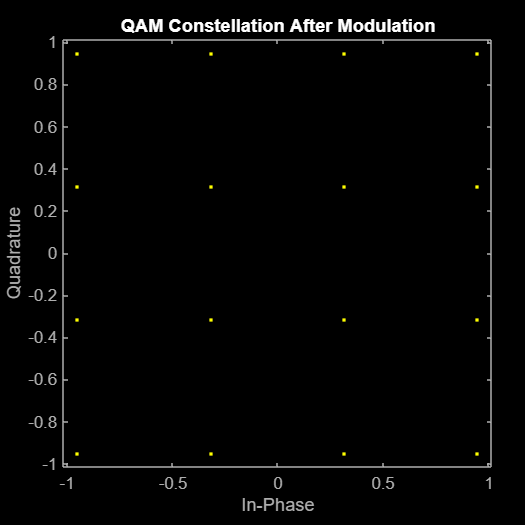

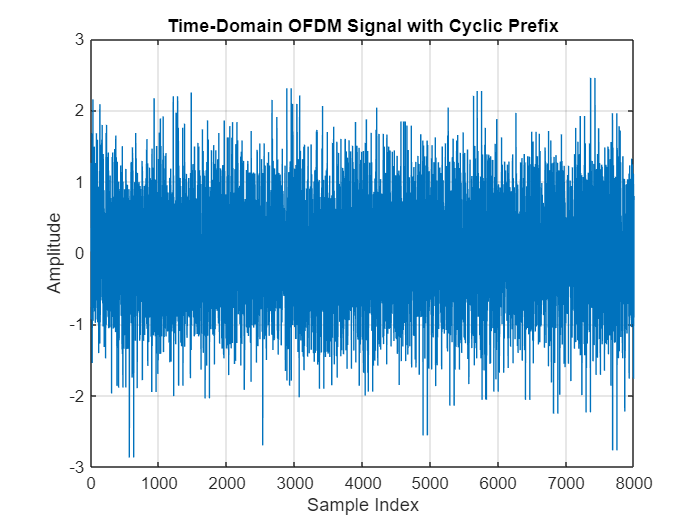

rng(100); % Set RNG for repeatability
[txWave,srcBits] = ...
    Waveform_Gen(modOrder,ofdmMod);

%Pass the waveform through the ray tracing channel model and add white noise
chanIn = [ repmat(txWave, 1, numTx) ;    ...
           zeros(fftLen+cpLen, numTx)   ];
[chanOut,CIR] = rtChan(chanIn);
rxWave = awgn(chanOut,SNRLin,numTx/numRx,'linear');

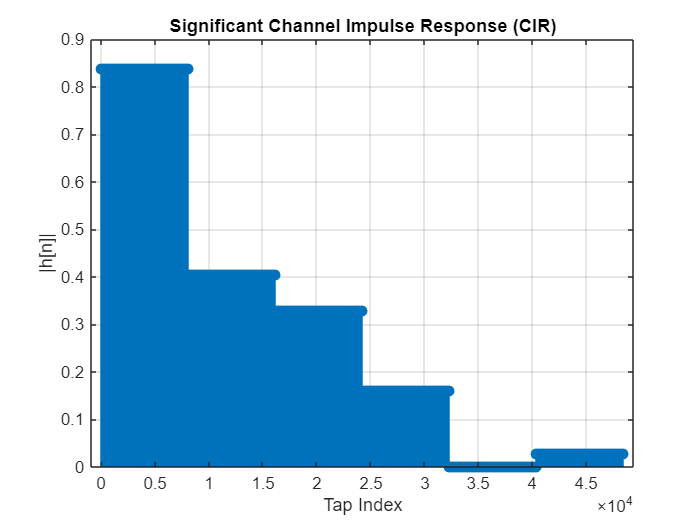

threshold = 1e-3;  % ignore near-zero taps
significantCIR = abs(CIR(:)) > threshold;

figure;
stem(find(significantCIR)-1, abs(CIR(significantCIR)), 'filled');
xlabel('Tap Index');
ylabel('|h[n]|');
title('Significant Channel Impulse Response (CIR)');
grid on;

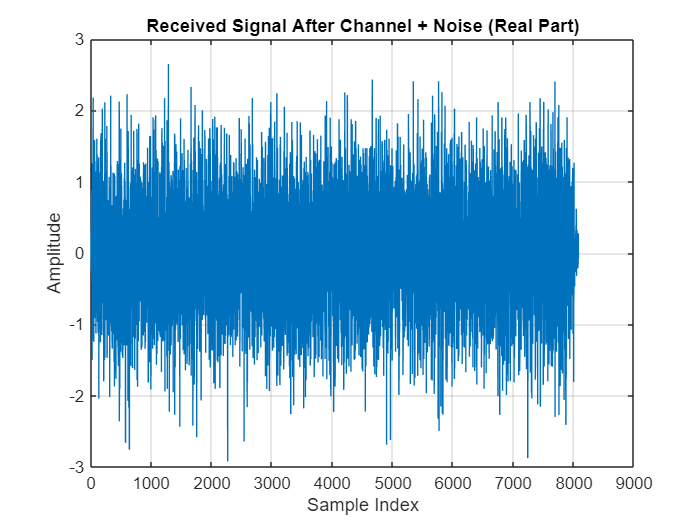


figure;
plot(real(rxWave));
xlabel('Sample Index');
ylabel('Amplitude');
title('Received Signal After Channel + Noise (Real Part)');
grid on;

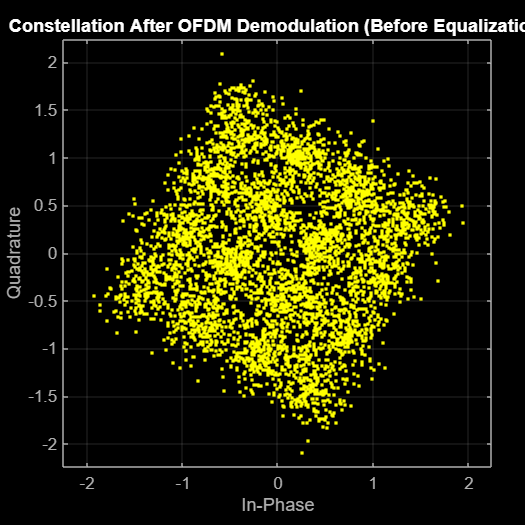

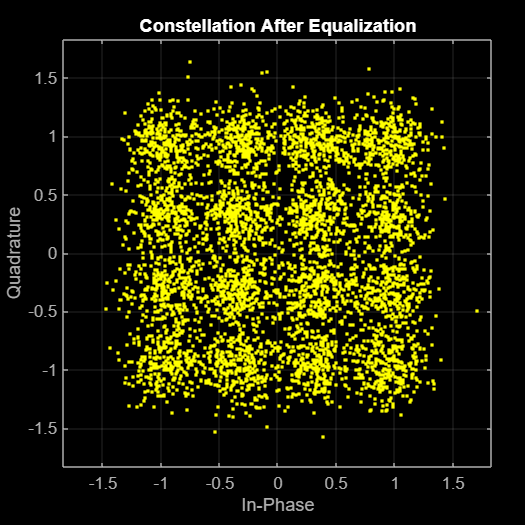

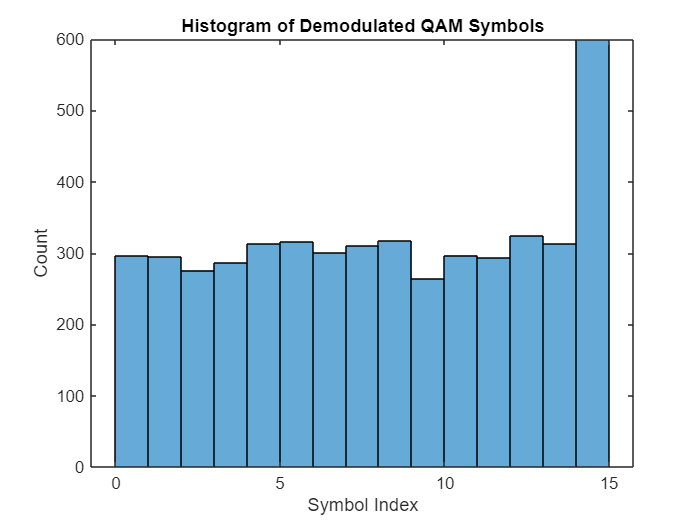

%recieve and decode stuff
[decBits, eqSym] = ...
    Rx_Processing(rxWave,CIR, ...
    rtChanInfo,modOrder,ofdmDemod);

errRate = comm.ErrorRate;
ber = errRate(srcBits,double(decBits));
disp(ber(1));

    0.0262

